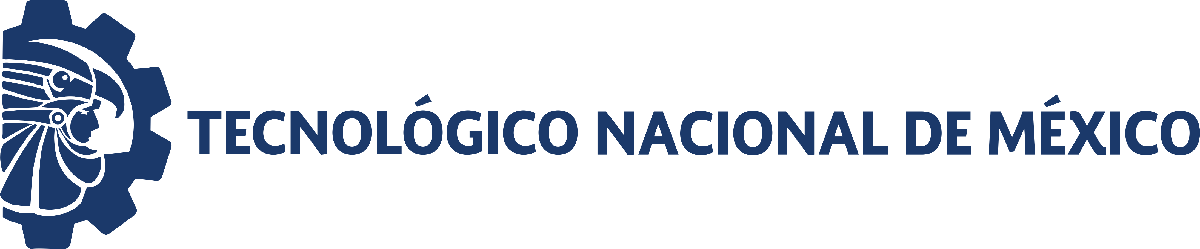                                 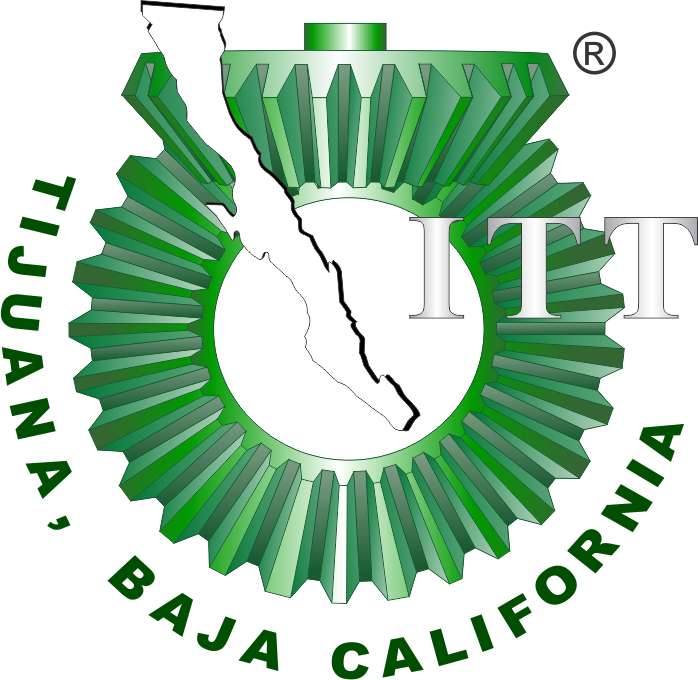

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

# Práctica 1: Sistema presa-depredador de Lotka-Volterra

**Objetivo. ** Aplicar el sistema de Lotka-Volterra para analizar los datos registrados en la interacción de dos especies articas, liebres (presa) y linces (depredador) durante 20 años. El sistema presa-depredador se formula mediante las siguientes dos EDOs de primer orden:


$$\dot x = \alpha x - \beta xy
$$



$$\dot y = \delta xy - \gamma y$$


donde los valores de los parámetros $\alpha$,$\beta ,$$\delta ,$$\gamma >0$, y las condiciones iniciales $x\left(0\right),$$y\left(0\right)>0$.

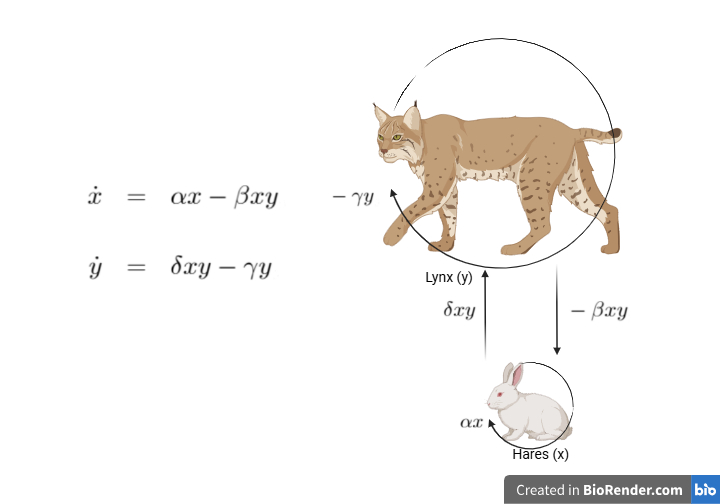

Figura. Generar la figura del sistema presa-depredador con [https://bioart.niaid.nih.gov/](https://bioart.niaid.nih.gov/) o [https://www.biorender.com/](https://www.biorender.com/).

## Referencias

[1] Valle, Paul A., Syllabus para Biología de Sistemas y Gemelos Digitales, Tecnológico Nacional de México / Instituto Tecnológico de Tijuana, Tijuana, B.C., México, 2026. Permalink: [https://biomath.xyz/course/](https://biomath.xyz/course/) 

[2] Garfinkel, Alan, Jane Shevtsov, and Yina Guo. Modeling life: the mathematics of biological systems. Springer International Publishing AG, 2017.

## Información general

Nombre del alumno: Alberto VIllalobso Vladez

Número de control: **22212277**

Correo institucional: l22212277**@tectijuana.edu.mx**

Asignatura: **Gemelos Digitales**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
smooth = false; normalize = false;
[to,xo,yo] = getdata('GEMELOS P1.csv',smooth,normalize);
plotsys(to,xo,yo); sgtitle('Datos experimentales');...
    exportgraphics(gcf,'data_raw.pdf','ContentType','vector')

## Procesamiento de datos

### Datos suavizados

smooth = true; normalize = false;
[to,xo,yo] = getdata('GEMELOS P1.csv',smooth, normalize);
plotsys(to,xo,yo); sgtitle('Datos suavizados');...
    exportgraphics(gcf,'data_smooth.pdf','ContentType','vector')

### Datos normalizados

smooth = false; normalize = true;
[to,xo,yo] = getdata('GEMELOS P1.csv',smooth, normalize);
plotsys(to,xo,yo); sgtitle('Datos normalizados');...
    exportgraphics(gcf,'data_normalized.pdf','ContentType','vector')

### Datos suavizados y normalizados

smooth = true; normalize = true;
[to,xo,yo] = getdata('GEMELOS P1.csv',smooth, normalize);
plotsys(to,xo,yo); sgtitle('Datos normalizados/suavizados');...
    exportgraphics(gcf,'data_sooth_normalized.pdf','ContentType','vector')

## Regresion no lineal

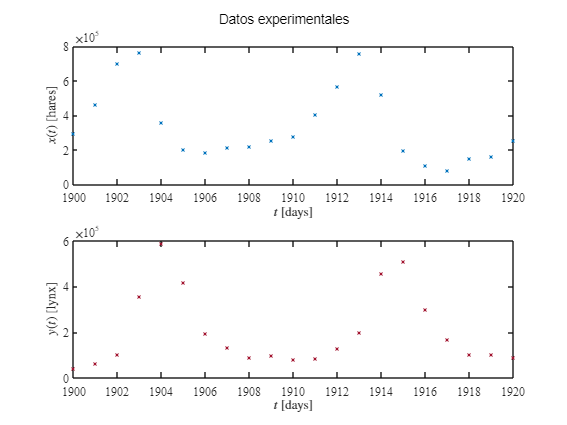

clear; close all
smooth = false; normalize = true;
[to,xo,yo] = getdata('GEMELOS P1.csv',smooth,normalize);
Po = [1; 1; 1; 1]; biostats = true;
mdl = Variant(to,xo,yo,Po,biostats);
fa = mdl.Fitted;
fa = reshape(fa,[],2);
xa = fa(:,1); ya = fa(:,2);
plotresults(to,xo,yo,to,xa,ya); sgtitle('Regresion no lineal');...
    exportgraphics(gcf,'data_nonlinear_regression.pdf','ContentType','vector')

## Prediccion del modelo a 2t

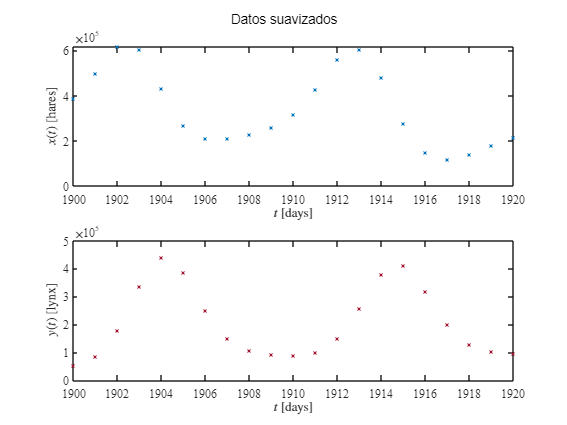

clear; close all
smooth = false; normalize = true;
[to,xo,yo] = getdata('GEMELOS P1.csv',smooth,normalize);
Po = [0.5;1.6;1.9;0.8]; biostats = false;
mdl = Variant(to,xo,yo,Po,biostats);
par = table2array(mdl.Coefficients(:,1));
alpha = par(1); beta = par(2); delta = par(3); gamma = par(4);

x0 = xo(1); y0 = yo(1); tend = to(end); dt = 1E-3;

### Metodo de Heun

[th,xh,yh] = sysheun(x0,y0,alpha,beta,delta,gamma,2*tend,dt);
plotresults(to,xo,yo,th,xh,yh); sgtitle('Heun: Predicción 2t');...
    exportgraphics(gcf,'heun.pdf','ContentType','vector')

### Metodo de Euler

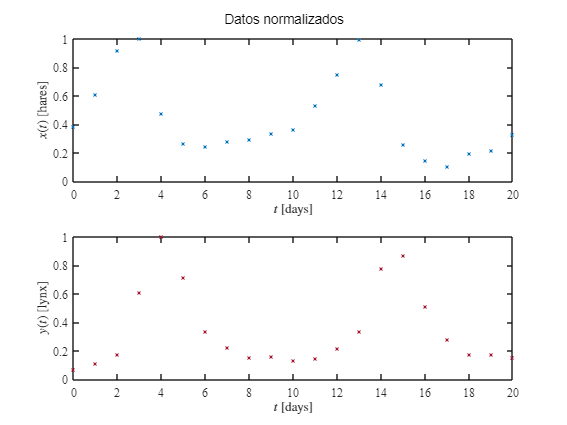

[te,xe,ye] = syseuler(x0,y0,alpha,beta,delta,gamma,2*tend,dt);

plotresults(to,xo,yo,th,xh,yh); sgtitle('Euler: Predicción 2t');...
    exportgraphics(gcf,'euler.pdf','ContentType','vector')

## Puntos de equilibrio

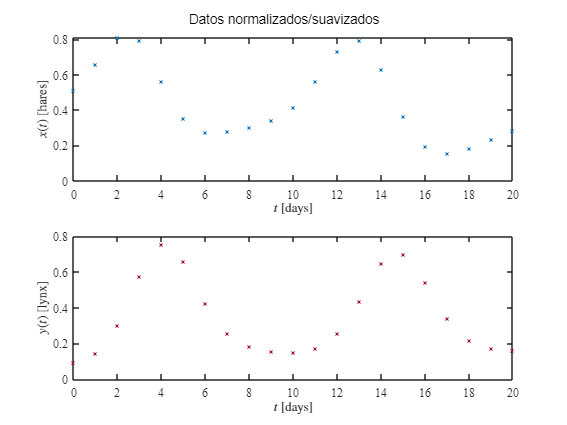

clc; clear
syms x y alpha beta delta gamma
dx_dt = alpha*x - beta*x*y == 0;

dy_dt = delta*x*y - gamma*y == 0;
fxy = solve([dx_dt,dy_dt],[x,y]);
fprintf(['Puntos de equilibrio del sistema: ',num2str(length(fxy.x))]);...
fprintf(['Puntos de equilibrio del sistema: ',num2str(length(fxy.y))])
xe_1 = fxy.x(1); ye_1 = fxy.y(1);
xe_2 = fxy.x(2); ye_2 = fxy.y(2);
fprintf('Puntos de equilibrio simbólicos: ');...

Degrees of freedom: 38
t-student value: 2.0244
Significance value (alpha): 0.05
    Parameters     Estimate       SE         MoE              CI95             Pvalue  
    ___________    ________    ________    ________    __________________    __________

    {["alpha"]}    0.56207     0.025487    0.051595    0.51048    0.61367    2.9358e-23
    {["beta" ]}     1.6811     0.097916     0.19822     1.4829     1.8793    1.6959e-19
    {["delta"]}     2.0034     0.094455     0.19121     1.8122     2.1946    1.1582e-22
    {["gamma"]}    0.81741     0.038472    0.077882    0.73952    0.89529    1.0902e-22

R-cuadrada ordinaria: 0.94763
R-cuadrada ajustada: 0.94349
Suma residual de cuadrados: 0.16795
Criterio de informacion de Akaike: -104.7234
Criterio de informacion de Akaike ajustado (n/

    disp([xe_1,ye_1;xe_2,ye_2])

## Soluciones y trayectoria

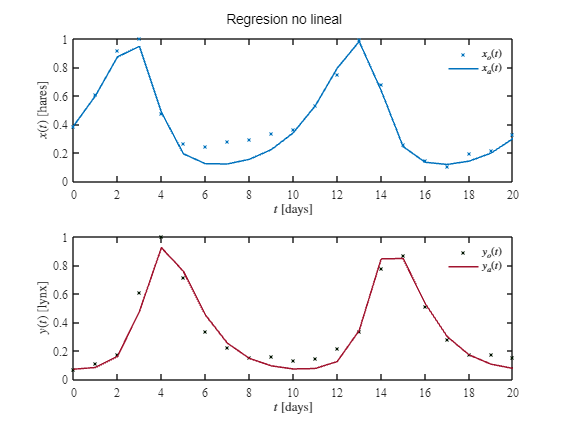

clear; close all
smooth = false; normalize = true;
[to,xo,yo] = getdata('GEMELOS P1.csv',smooth,normalize);
Po = [0.5;1.6;1.9;0.8]; biostats = false;

mdl = Variant(to,xo,yo,Po,biostats);
par = table2array(mdl.Coefficients(:,1));
alpha = par(1); beta = par(2); delta = par(3); gamma = par(4);
x0 = xo(1); y0 = yo(1); tend = to(end); dt = 1E-3;
[th,xh,yh] = sysheun(x0,y0,alpha,beta,delta,gamma,2*tend,dt);
plotedos(th,xh,yh,par); exportgraphics(gcf,'phase_plane.pdf','ContentType','vector')

### Influencia de dt en la aproximacion de las soluciones: Euler

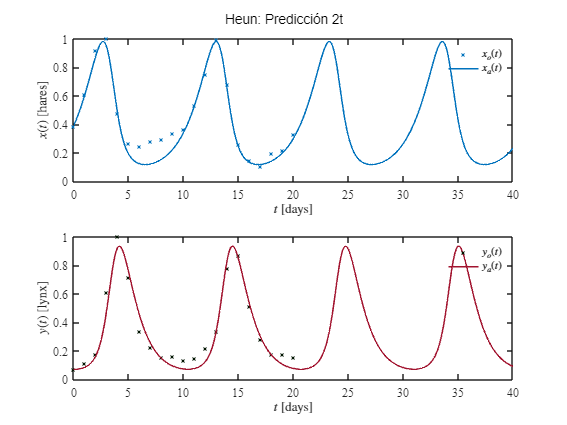

clear; close all
smooth = false; normalize = true;
[to,xo,yo] = getdata('GEMELOS P1.csv',smooth,normalize);
Po = [0.5;1.6;1.9;0.8]; biostats = false;
mdl = Variant(to,xo,yo,Po,biostats);
par = table2array(mdl.Coefficients(:,1));
alpha = par(1); beta = par(2); delta = par(3); gamma = par(4);
x0 = xo(1); y0 = yo(1); tend = to(end);

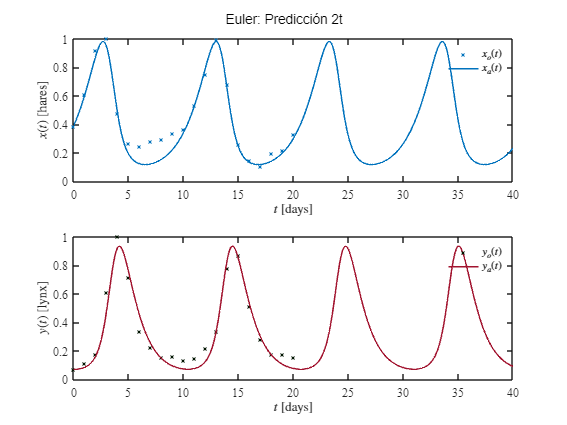

dt =[2;1;0.5;0.25;0.1;1E-2;1E-3;1E-4;1E-5;1E-6;1E-7];
for i = 1:length(dt)
    [te,xe,ye] = syseuler(x0,y0,alpha,beta,delta,gamma,2*tend,dt(i));
    plotedos(te,xe,ye,par);  sgtitle(['dt value = ', num2str(dt(i))]);...

        exportgraphics(gcf,['euler_',num2str(dt(i)),'.pdf'],'ContentType','vector')
end

### Influencia de dt en la aproximacion de las soluciones: Heun

clear; close all
smooth = false; normalize = true;
[to,xo,yo] = getdata('GEMELOS P1.csv',smooth,normalize);
Po = [0.5;1.6;1.9;0.8]; biostats = false;
mdl = Variant(to,xo,yo,Po,biostats);
par = table2array(mdl.Coefficients(:,1));
alpha = par(1); beta = par(2); delta = par(3); gamma = par(4);

Puntos de equilibrio del sistema: 2

Puntos de equilibrio del sistema: 2

x0 = xo(1); y0 = yo(1); tend = to(end);
dt =[2;1;0.5;0.25;0.1;1E-2;1E-3;1E-4;1E-5;1E-6;1E-7];
for i = 1:length(dt)
    [th,xh,yh] = sysheun(x0,y0,alpha,beta,delta,gamma,2*tend,dt(i));

Puntos de equilibrio simbólicos: 

$$\left(\begin{array}{cc} 0 & 0\\ \frac{\gamma }{\delta } & \frac{\alpha }{\beta } \end{array}\right)$$

    plotedos(th,xh,yh,par);  sgtitle(['dt value = ', num2str(dt(i))]);...
        exportgraphics(gcf,['heun_',num2str(dt(i)),'.pdf'],'ContentType','vector')
end


## Soluciones/trayectorias positivamente invariantes

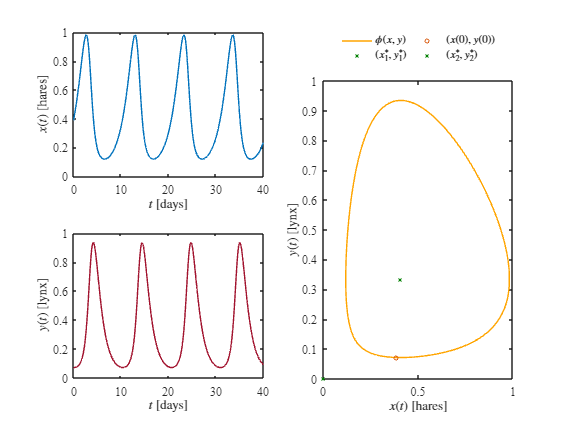

clear; close all
smooth = false; normalize = true;
[to,xo,yo] = getdata('GEMELOS P1.csv',smooth,normalize);
Po = [0.5;1.6;1.9;0.8]; biostats = false;
mdl = Variant(to,xo,yo,Po,biostats);
par = table2array(mdl.Coefficients(:,1));
alpha = par(1); beta = par(2); delta = par(3); gamma = par(4);
x0 = xo(1); y0 = yo(1); tend = to(end); dt =1E-3;

x0 = [xo(1),0,gamma/delta,0.25,0.5,0.75,1,gamma/delta,0,alpha/beta,-0.1,0.1,-0.1,0.001,0.001,1,1]; 
y0 = [yo(1),0,alpha/beta,0.25,0.5,0.75,1,0,alpha/beta,gamma/delta,0.1,-0.1,-0.1,0.001,1,0.001,1];
for i = 1:length(x0)
    [t,x,y] = sysheun(x0(i),y0(i),alpha,beta,delta,gamma,5*tend,dt);
    plotedos(t,x,y,par); sgtitle(['(x(0),y(0)) = (', num2str(x0(i)),',',num2str(y0(i)),')']);...
        exportgraphics(gcf,['initial_conditions ',num2str((i)),'.pdf'],'ContentType','vector')
end

## Simulink

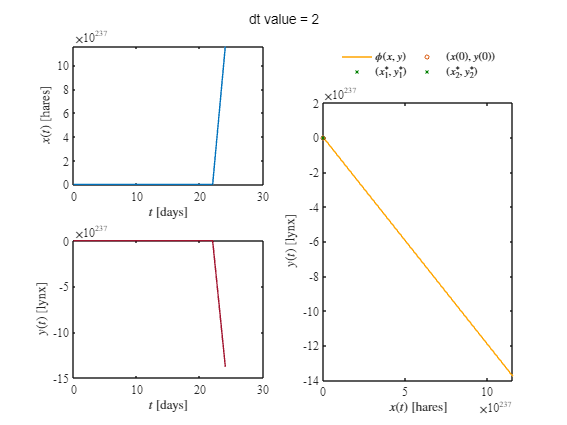

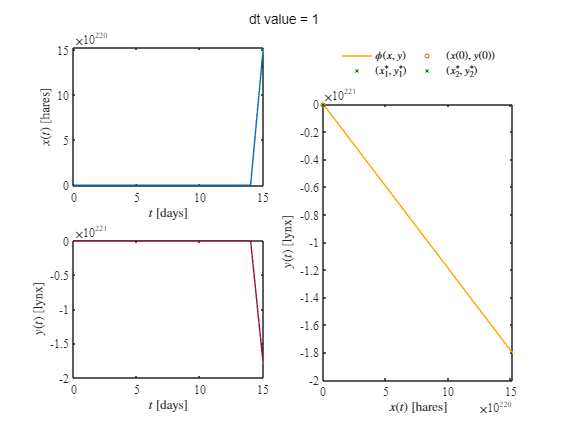

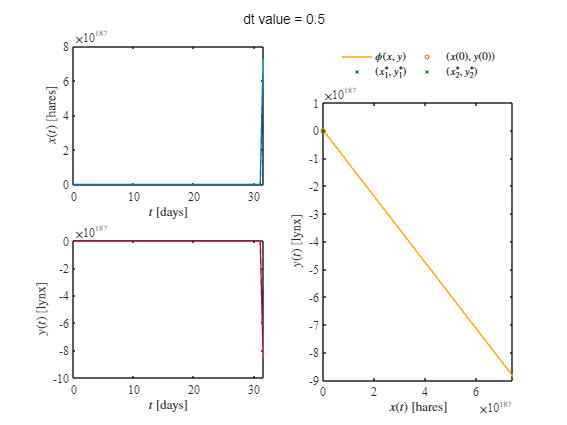

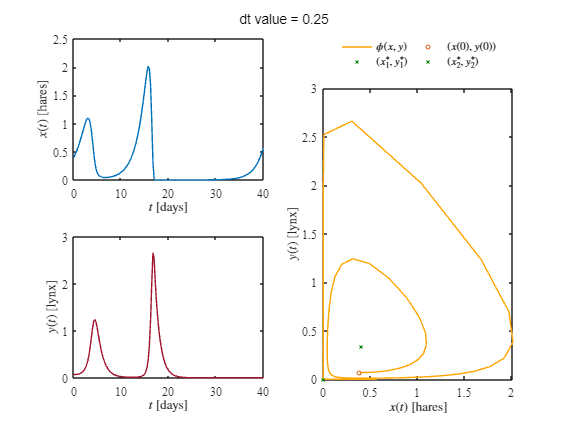

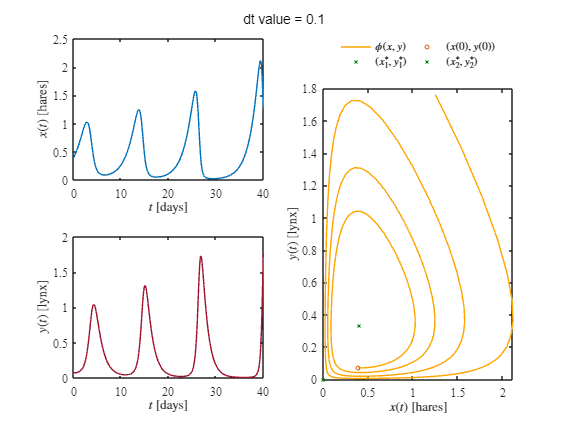

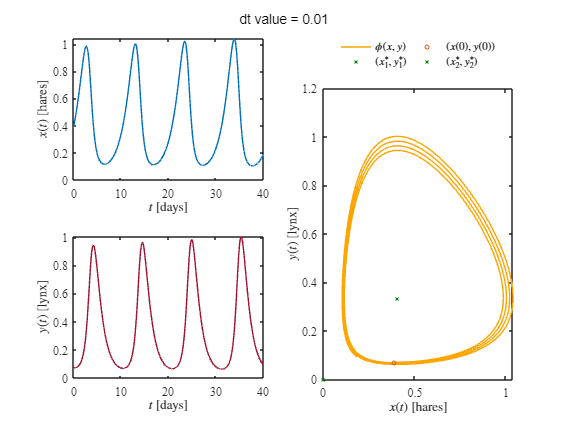

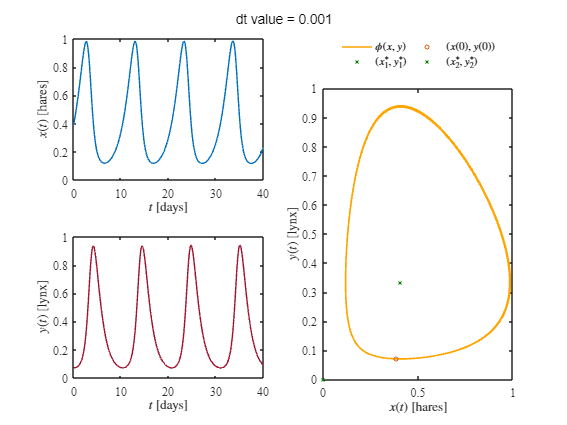

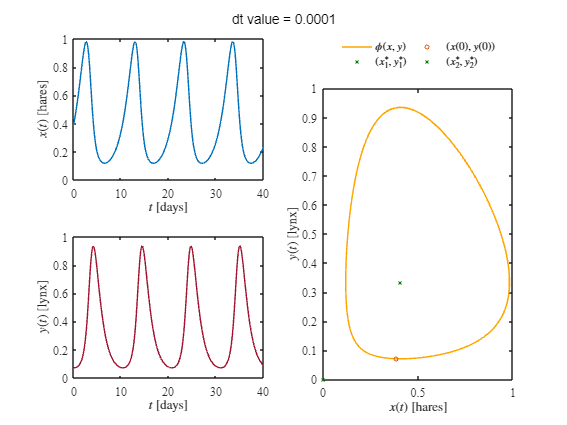

clear; close all
smooth = false; normalize = true;
[to,xo,yo] = getdata('GEMELOS P1.csv',smooth,normalize);
Po = [0.5;1.6;1.9;0.8]; biostats = false;
mdl = Variant(to,xo,yo,Po,biostats);
par = table2array(mdl.Coefficients(:,1));
file = 'LOTKAVOLTERRA';
sim(file);
parameters.StopTime = '100';

### **odes para soluciones *****stiff***

#### **Funcion ode15s**

clear; close all
smooth = false; normalize = true;
[to,xo,yo] = getdata('GEMELOS P1.csv',smooth,normalize);
Po = [0.5;1.6;1.9;0.8]; biostats = false;
mdl = Variant(to,xo,yo,Po,biostats);
par = table2array(mdl.Coefficients(:,1));
parameters.Solver = 'ode15s';
file = 'LOTKAVOLTERRA';
f = sim(file,parameters); 
plotedos(f.t,f.x,f.y,par);sgtitle('Simulink : ode15s'); 
    exportgraphics(gcf,'ode15s.pdf','ContentType','vector');

#### **Funcion ode23s**

parameters.Solver = 'ode23s';
f = sim(file,parameters);
plotedos(f.t,f.x,f.y,par); sgtitle('Simulink : ode23s');
exportgraphics(gcf,'ode23s.pdf','ContentType','vector');

#### **Funcion ode23tF**

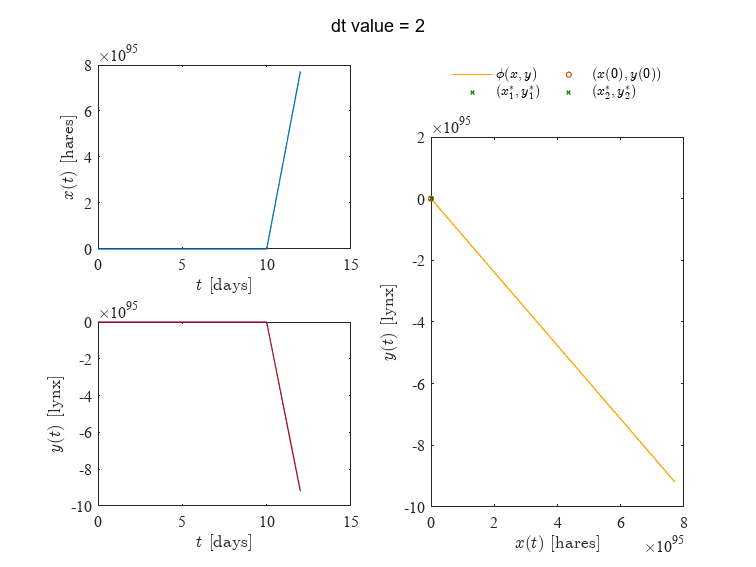

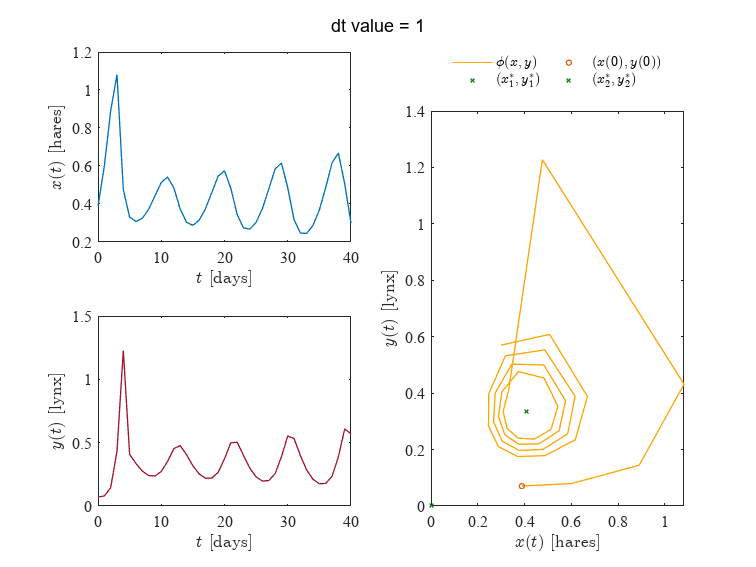

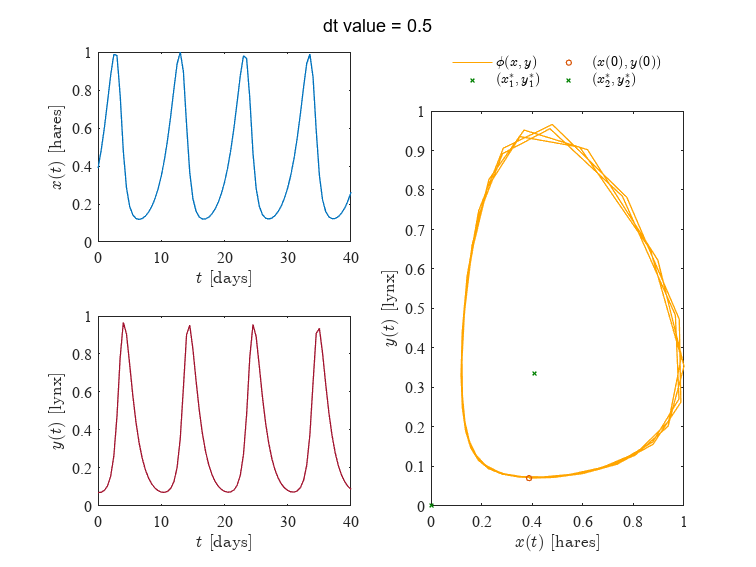

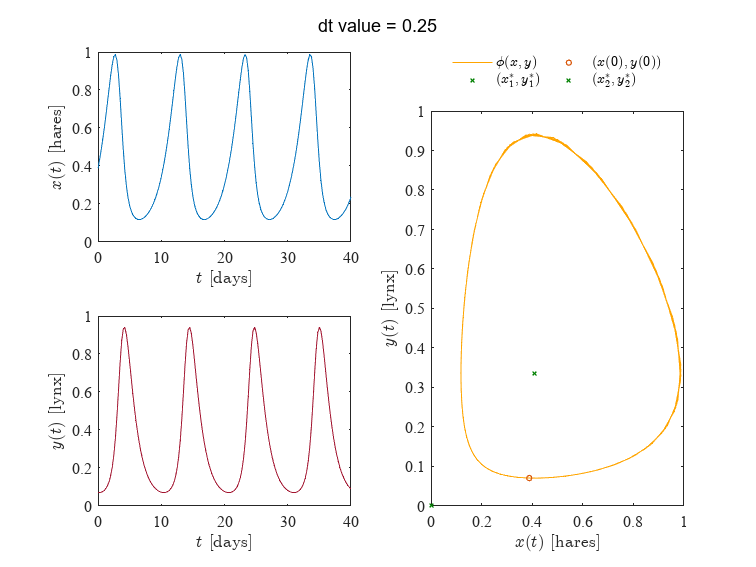

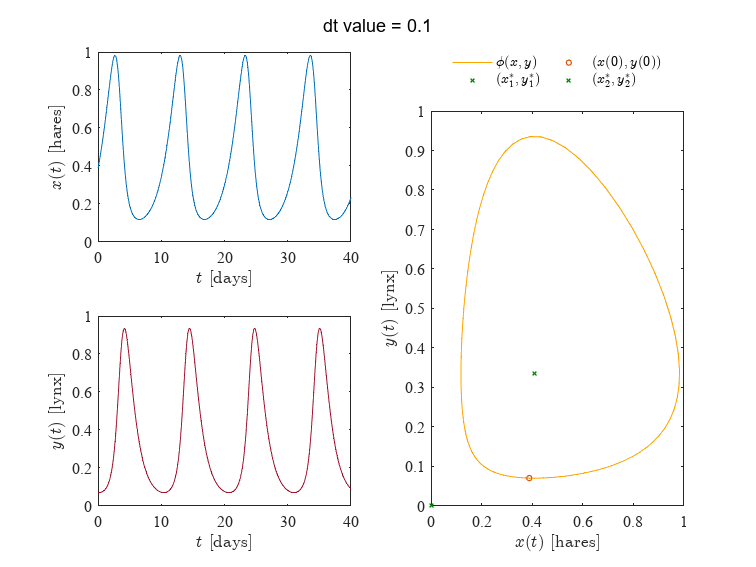

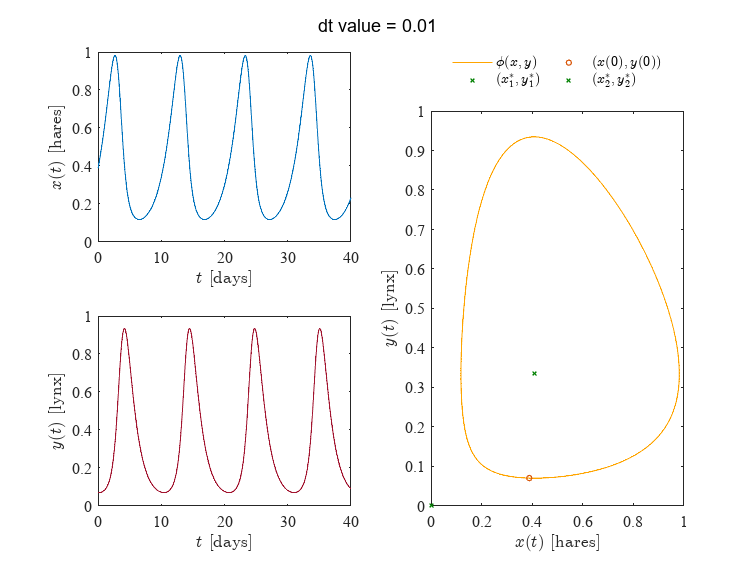

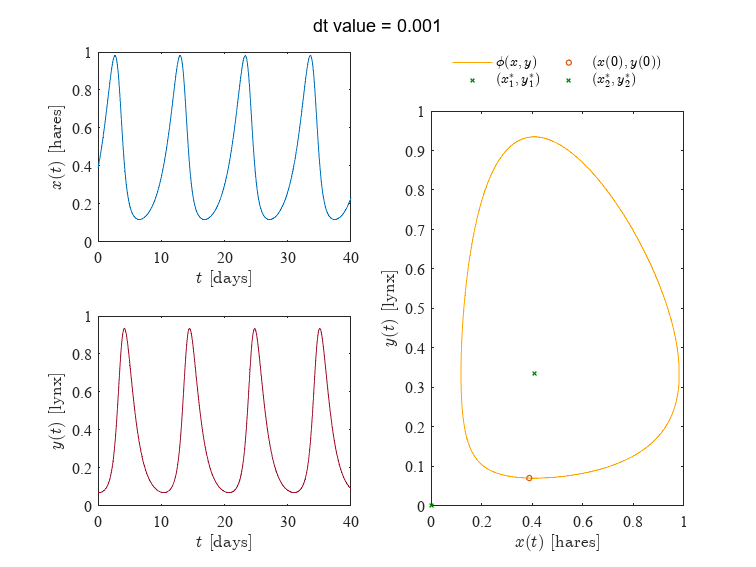

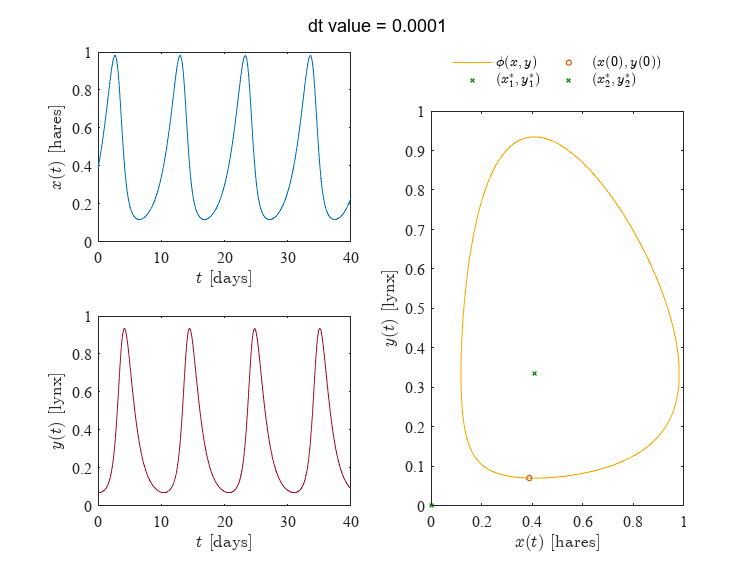

parameters.Solver = 'ode23t';

f = sim(file,parameters);f
plotedos(f.t,f.x,f.y,par);sgtitle('Simulink : ode23t'); 
exportgraphics(gcf,'ode23t.pdf','ContentType','vector');

#### **Funcion ode23tb**

parameters.Solver = 'ode23tb';
f = sim(file,parameters);
plotedos(f.t,f.x,f.y,par);sgtitle('Simulink : ode23tb'); 
exportgraphics(gcf,'ode23tb.pdf','ContentType','vector');

### **odes para soluciones *****nonstiff***

#### **Funcion ode45**

parameters.Solver = 'ode45';
f = sim(file,parameters);
plotedos(f.t,f.x,f.y,par);sgtitle('Simulink : ode45'); 
exportgraphics(gcf,'ode45.pdf','ContentType','vector');

#### **Funcion ode23**

parameters.Solver = 'ode23';
f = sim(file,parameters);
plotedos(f.t,f.x,f.y,par);sgtitle('Simulink : ode23'); 
exportgraphics(gcf,'ode23.pdf','ContentType','vector');

#### **Funcion ode113**

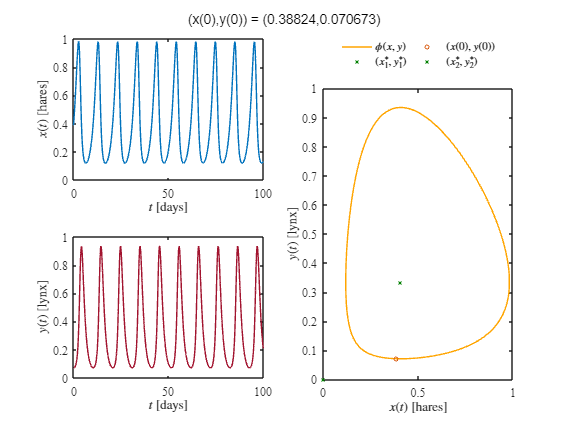

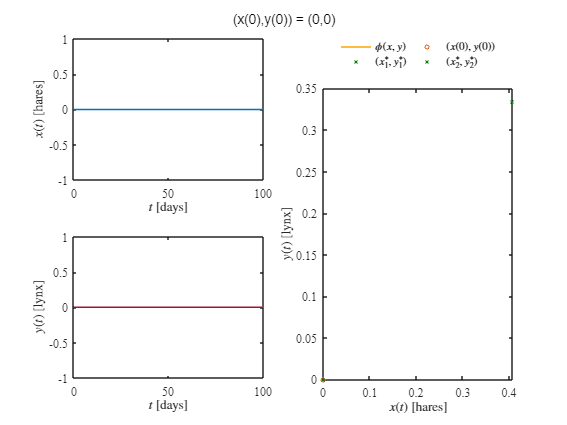

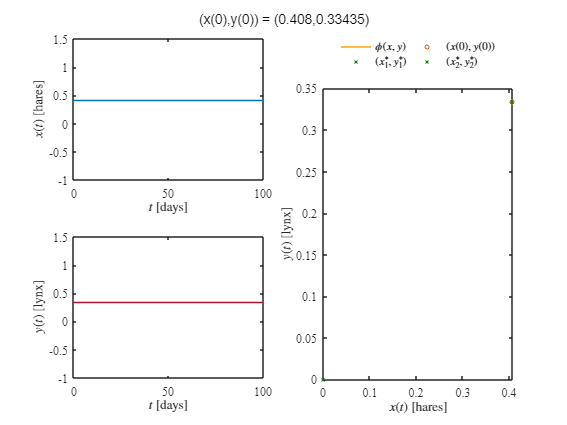

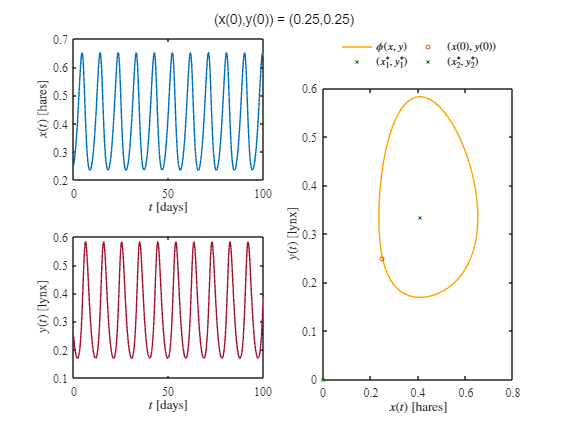

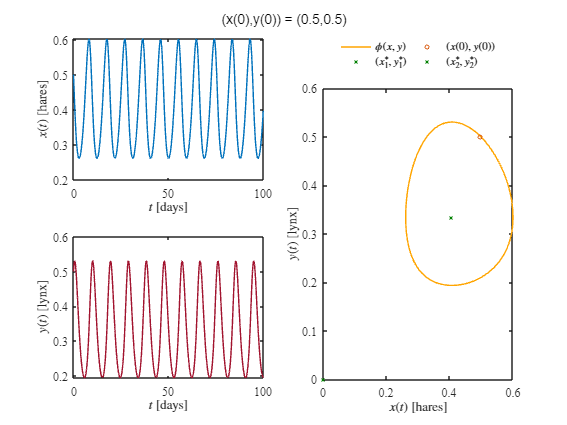

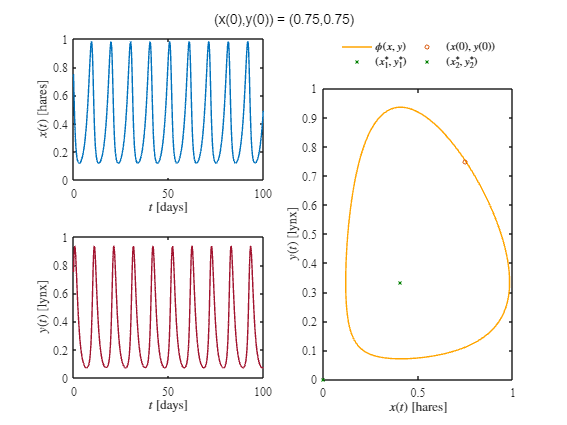

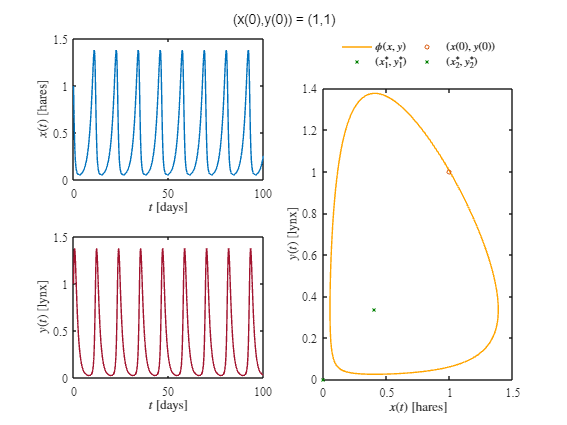

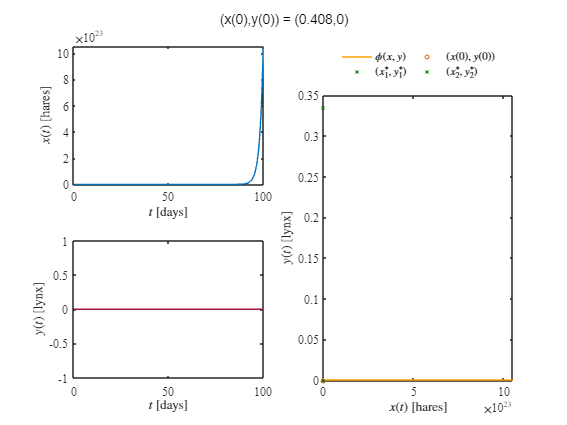

parameters.Solver = 'ode113';
f = sim(file,parameters);
plotedos(f.t,f.x,f.y,par); sgtitle('Simulink : ode113');

    exportgraphics(gcf,'ode113.pdf','ContentType','vector');

#### **Funcion ode1**

clear; close all
smooth = false; normalize = true;
[to,xo,yo] = getdata('GEMELOS P1.csv',smooth,normalize);
Po = [0.5;1.6;1.9;0.8]; biostats = false;
mdl = Variant(to,xo,yo,Po,biostats);
par = table2array(mdl.Coefficients(:,1));
file = 'LOTKAVOLTERRA';
sim(file);
parameters.StopTime = '100';
parameters.Solver = 'ode1';
parameters.FixedStep = '1E-4';
f = sim(file,parameters);
plotedos(f.t,f.x,f.y,par); sgtitle('Simulink : ode1, FixedStep = 1E-4');
exportgraphics(gcf,'ode1.pdf','ContentType','vector');

#### **Funcion ode2**

parameters.Solver = 'ode2';
parameters.FixedStep = '1E-1';
f = sim(file,parameters);
plotedos(f.t,f.x,f.y,par);sgtitle('Simulink : ode2, FixedStep = 1E-1'); 
exportgraphics(gcf,'ode2.pdf','ContentType','vector');

#### **Funcion ode3**

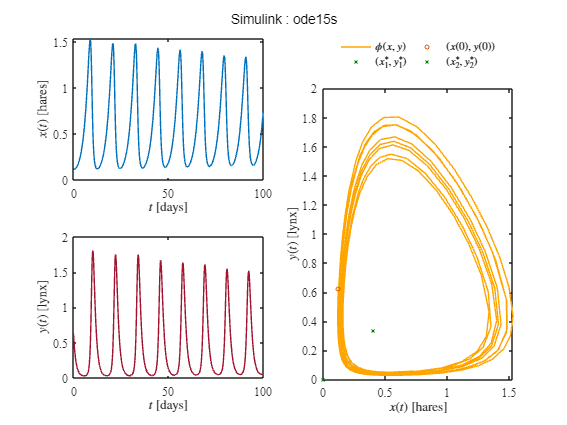

parameters.Solver = 'ode3';
parameters.FixedStep = '1E-1';
f = sim(file,parameters);
plotedos(f.t,f.x,f.y,par);sgtitle('Simulink : ode3, FixedStep = 1E-1'); 
exportgraphics(gcf,'ode3.pdf','ContentType','vector');

#### **Funcion ode4**

parameters.Solver = 'ode4';
parameters.FixedStep = '1E-1';
f = sim(file,parameters);
plotedos(f.t,f.x,f.y,par);sgtitle('Simulink : ode4, FixedStep = 1E-1');
exportgraphics(gcf,'ode4.pdf','ContentType','vector');

#### **Funcion ode5**

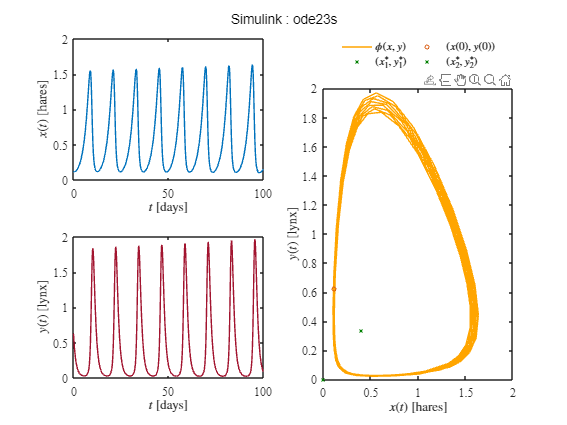

parameters.Solver = 'ode5';

parameters.FixedStep = '1E-1';
f = sim(file,parameters);
plotedos(f.t,f.x,f.y,par); sgtitle('Simulink : ode5, FixedStep = 1E-1');
exportgraphics(gcf,'ode5.pdf','ContentType','vector');

f =   Simulink.SimulationOutput:

                      t: [327x1 double] 
                      x: [327x1 double] 
                      y: [327x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


### **Funcion ode113 con paso maximo = 1E-3**

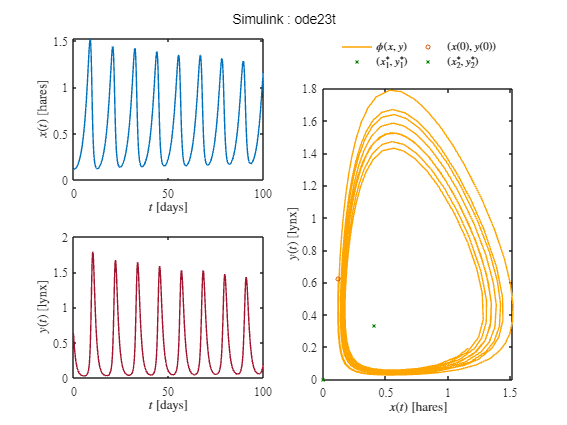

parameters.Solver = 'ode113';
parameters.MaxStep = '1E-3';

f = sim(file,parameters);
plotedos(f.t,f.x,f.y,par); sgtitle('Simulink : ode113, MaxStep = 1E-3'); 
exportgraphics(gcf,'ode113MaxStep.pdf','ContentType','vector');

## Funciones odes

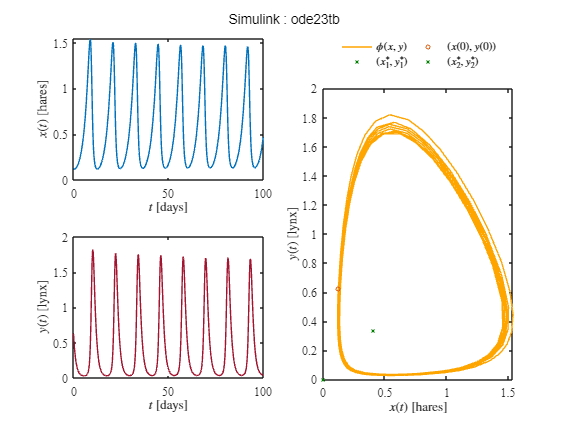

clear; close all
smooth = false; normalize = true;
[to,xo,yo] = getdata('GEMELOS P1.csv',smooth,normalize);

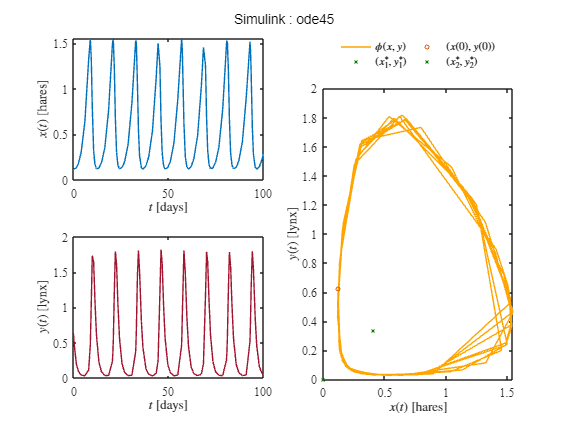

Po = [0.5;1.6;1.9;0.8]; biostats = false;
mdl = Variant(to,xo,yo,Po,biostats);
par = table2array(mdl.Coefficients(:,1));
x0 = xo(1); y0=yo(1);
[t,solV] = ode89(@(t,V) sysODE(V,par) ,[0,100],[x0,y0]);
x = solV(:,1);
y = solV(:,2);

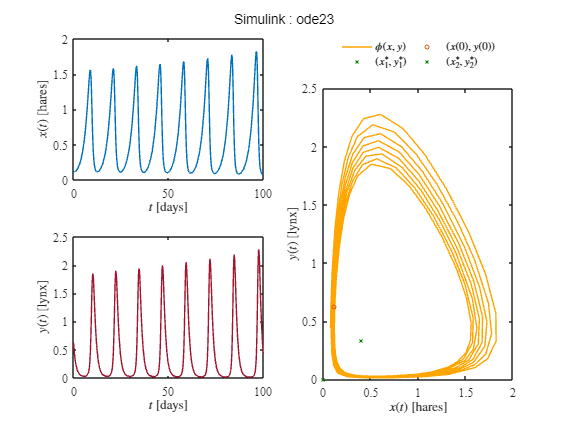

plotedos(t,x,y,par);sgtitle('Simulink : ode89, tspan variable');
    exportgraphics(gcf,'simulinkode89tsv.pdf','ContentType','vector');
dt = 1E-3;
tspan = (0:dt:100)';
[ti,solVi] = ode89(@(t,V) sysODE(V,par) ,tspan,[x0,y0]);
xi = solVi(:,1);

yi = solVi(:,2);
plotedos(ti,xi,yi,par);sgtitle('Simulink : ode89, tspan fijo');
    exportgraphics(gcf,'simulinkode89tsf.pdf','ContentType','vector');

## Prediccion con los datos experimentales

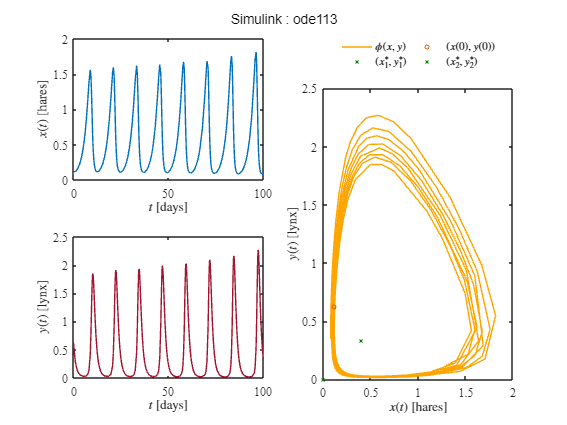

clear; close all
smooth = false; normalize = true;
[to,xo,yo] = getdata('GEMELOS P1.csv',smooth,normalize);

tend = to(end);
Po = [0.5;1.6;1.9;0.8]; biostats = false;
mdl = Variant(to,xo,yo,Po,biostats);
par = table2array(mdl.Coefficients(:,1));
alpha = par(1); beta = par(2); delta = par(3); gamma = par(4);
smooth = false; normalize = false;
[to,xo,yo] = getdata('GEMELOS P1.csv',smooth,normalize);
betat = beta/max(yo); deltat = delta/max(xo); 
dt=1E-3; x0 = xo(1) ; y0=yo(1);
[th,xh,yh] = sysheun(x0,y0,alpha,betat,deltat,gamma,2*tend,dt);
plotresults(to,xo,yo,th+to(1),xh,yh);   sgtitle(['Prediccion con datos experimentales']);...
    exportgraphics(gcf,['prediccionexperimental.pdf'],'ContentType','vector')

## Funciones

### Soluciones y trayectoria en el plano de fase

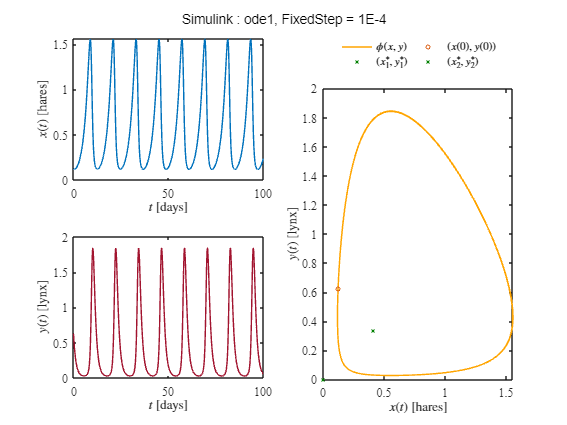

function plotsys(to,xo,yo)
    set(figure(),'color','w')
    FS = 12;
    set(gcf,'Units','Centimeters','Position',[1,1,20,15])

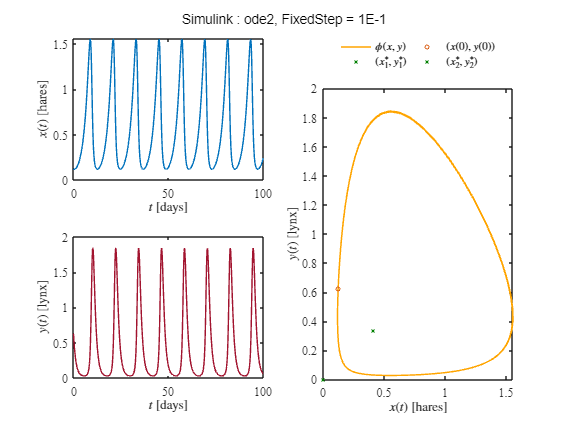

    subplot(2,1,1)
    hold on; box on; grid off;
    plot(to,xo,'x','LineWidth',1,'MarkerSize',4,'Color',[0, 0.447, 0.741])
    xlabel('$t$ [days]','Interpreter','Latex','FontSize',FS)
    ylabel('$x(t)$ [hares]','Interpreter','Latex','FontSize',FS)
    set(gca,'FontName','Times New Roman','FontSize',FS)


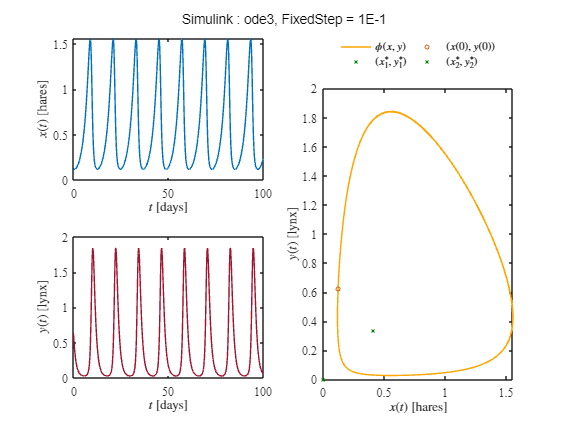

    subplot(2,1,2)
    hold on; box on; grid off;
    plot(to,yo,'x','LineWidth',1,'MarkerSize',4,'Color',[0.635, 0.078, 0.184])
    xlabel('$t$ [days]','Interpreter','Latex','FontSize',FS)
    ylabel('$y(t)$ [lynx]','Interpreter','Latex','FontSize',FS)
    set(gca,'FontName','Times New Roman','FontSize',FS)
end

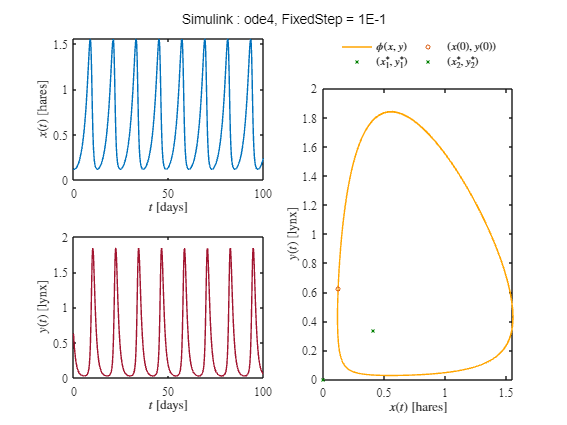


function plotedos(t,x,y,P)
    set(figure(),'color','w')
    FS = 12;
    set(gcf,'Units','Centimeters','Position',[1,1,20,15])
    subplot(2,2,1)
    hold on; box on; grid off;

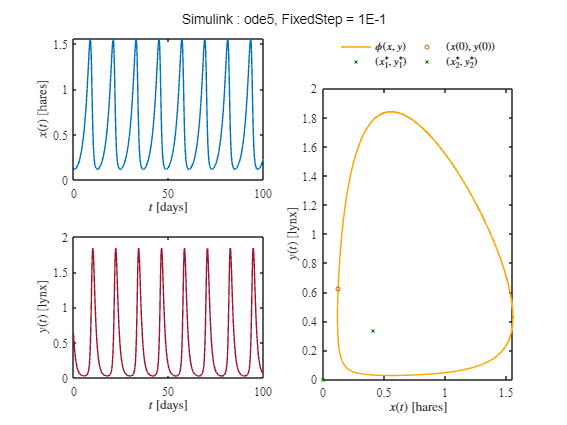

    plot(t,x,'-','LineWidth',1,'MarkerSize',4,'Color',[0, 0.447, 0.741])
    xlabel('$t$ [days]','Interpreter','Latex','FontSize',FS)
    ylabel('$x(t)$ [hares]','Interpreter','Latex','FontSize',FS)
    set(gca,'FontName','Times New Roman','FontSize',FS)

    subplot(2,2,3)
    hold on; box on; grid off;

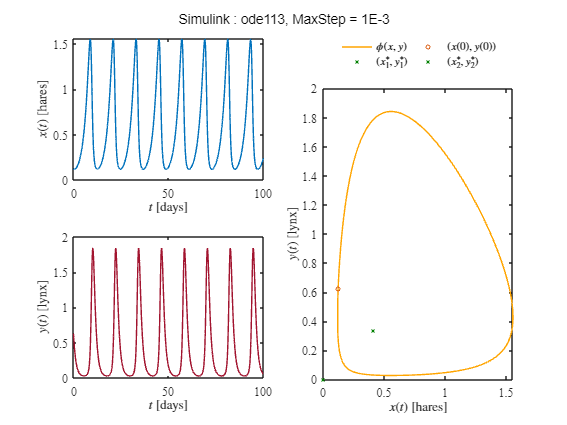

    plot(t,y,'-','LineWidth',1,'MarkerSize',4,'Color',[0.635, 0.078, 0.184])
    xlabel('$t$ [days]','Interpreter','Latex','FontSize',FS)
    ylabel('$y(t)$ [lynx]','Interpreter','Latex','FontSize',FS)
    set(gca,'FontName','Times New Roman','FontSize',FS)

    subplot(2,2,[2 4])
    hold on; box on; grid off;

    alpha = P(1); beta = P(2); delta = P(3); gamma = P(4);
    plot(x,y,'-','LineWidth',1,'Color',[255, 165, 0]/255)
    plot(x(1),y(1),'o','LineWidth',1,'MarkerSize',4,'Color',[0.85,0.35,0.05])
    plot(0,0,'x','LineWidth',1,'MarkerSize',4,'Color',[0, 128, 0]/255)
    plot(gamma/delta,alpha/beta,'x','LineWidth',1,'LineWidth',1,'MarkerSize',4,'Color',[0, 128, 0]/255)
    L = legend('$\phi(x,y)$','$(x(0),y(0))$','$(x^*_1,y^*_1)$','$(x^*_2,y^*_2)$');
    set(L, 'Interpreter','Latex','Location','NorthOutside','Orientation','Horizontal',...
        'Box','Off','NumColumns',2)
    xlabel('$x(t)$ [hares]','Interpreter','Latex','FontSize',FS)
    ylabel('$y(t)$ [lynx]','Interpreter','Latex','FontSize',FS)
    set(gca,'FontName','Times New Roman','FontSize',FS)
end

### Ajuste por regresión no lineal

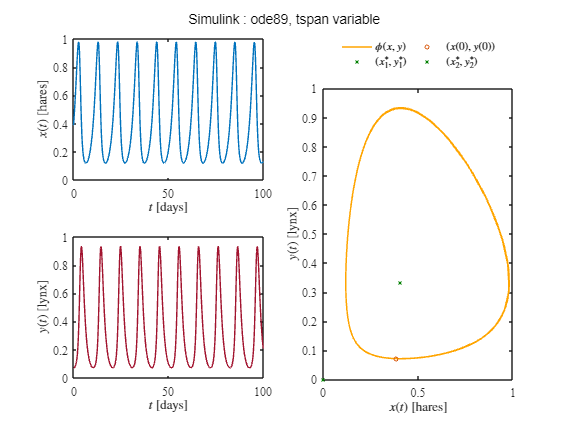

function mdl = Variant(to,xo,yo,Po,biostats)
    x0 = xo(1); y0 = yo(1);

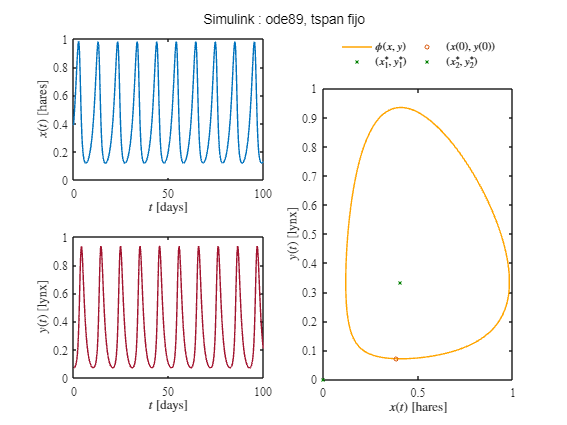

    t = [to;to];
    fo = [xo;yo];
    
    function fa = model(pa,ta)
        alpha = pa(1); beta = pa(2); delta = pa(3); gamma = pa(4);
        dt = 1E-1;
        time = (0:dt:max(ta))';

        x = zeros(length(time),1); x(1) = x0;
        y = zeros(length(time),1); y(1) = y0;
        n = round(max(ta)/dt);

        for i = 1:n %metodo de Heun
            [fx,fy] = f(x(i),y(i));
            xn = x(i) + fx*dt;
            yn = y(i) + fy*dt;
            [fxn,fyn] = f(xn,yn);
            x(i+1) = x(i) + (fx + fxn)*dt/2;
            y(i+1) = y(i) + (fy + fyn)*dt/2;
        end

        function [dx,dy] = f(x,y)
            dx = alpha*x - beta*x*y;
            dy = delta*x*y - gamma*y;
        end

        xi = interp1(time, x, to, 'linear');
        yi = interp1(time, y, to, 'linear');

        fa = [xi;yi];
    end

    mdl = fitnlm(t,fo,@model,Po);

    if biostats == true
        Estimate = table2array(mdl.Coefficients(:,1));
        SE = table2array(mdl.Coefficients(:,2));
        Pvalue = table2array(mdl.Coefficients(:,4));
        alpha = 0.05;
        CI95 = coefCI(mdl,alpha);
        dof = mdl.DFE;
        tval = tinv(1-alpha/2,dof);
        MoE = SE*tval;
        Parameters = {"alpha"; "beta"; "delta"; "gamma"};
        Results = table(Parameters,Estimate,SE,MoE,CI95,Pvalue);
        disp(['Degrees of freedom: ',num2str(dof)])
        disp(['t-student value: ',num2str(tval)])
        disp(['Significance value (alpha): ',num2str(alpha)])
        disp(''); disp(Results)
        R2o = mdl.Rsquared.Ordinary;
        R2a = mdl.Rsquared.Adjusted;
        SSE = mdl.SSE;
        AIC = mdl.ModelCriterion.AIC;
        AICc = mdl.ModelCriterion.AICc;
        fprintf(['R-cuadrada ordinaria: ', num2str(R2o)]);...
        fprintf(['\nR-cuadrada ajustada: ', num2str(R2a)]);...
        fprintf(['\nSuma residual de cuadrados: ', num2str(SSE)]);...
        fprintf(['\nCriterio de informacion de Akaike: ', num2str(AIC)]);...
        fprintf(['\nCriterio de informacion de Akaike ajustado (n/k<40): ', num2str(AICc)]);
    end
end

function plotresults(to, xo, yo, ta, xa, ya)
    set(figure(), 'color', 'w')
    FS = 12; 
    set(gcf, 'Units', 'Centimeters', 'Position', [1,1,20,15])

    subplot(2,1,1)
    hold on; box on; grid off;
    plot(to, xo, 'x', 'LineWidth', 1, 'MarkerSize', 4, 'Color', [0, 0.447, 0.741], 'DisplayName', '$x_o(t)$')
    plot(ta, xa, '-', 'LineWidth', 1.5, 'Color', [0, 0.447, 0.741], 'DisplayName', '$x_a(t)$')
    xlabel('$t$ [days]', 'Interpreter', 'Latex', 'FontSize', FS)
    ylabel('$x(t)$ [hares]', 'Interpreter', 'Latex', 'FontSize', FS)
    legend('Location', 'northeast', 'Interpreter', 'Latex')
    legend boxoff
    set(gca, 'FontName', 'Times New Roman', 'FontSize', FS)

    subplot(2,1,2)
    hold on; box on; grid off;
    plot(to, yo, 'x', 'LineWidth', 1, 'MarkerSize', 4, 'Color', [0, 0.078, 0], 'DisplayName', '$y_o(t)$')
    plot(ta, ya, '-', 'LineWidth', 1.5, 'Color', [0.635, 0.078, 0.184], 'DisplayName', '$y_a(t)$')
    xlabel('$t$ [days]', 'Interpreter', 'Latex', 'FontSize', FS)
    ylabel('$y(t)$ [lynx]', 'Interpreter', 'Latex', 'FontSize', FS)
    legend('Location', 'northeast', 'Interpreter', 'Latex')
    legend boxoff
    set(gca, 'FontName', 'Times New Roman', 'FontSize', FS)
end

### Método de Euler

function [t,x,y] = syseuler(x0,y0,alpha,beta,delta,gamma,tend,dt)
    n = round(tend/dt);
    t = (0:dt:tend)';
    x = zeros(length(t), 1); x(1) = x0;
    y = zeros(length(t), 1); y(1) = y0;

    for i = 1:n 
        [fx,fy] = f(x(i), y(i));
        x(i+1) = x(i) + fx * dt;
        y(i+1) = y(i) + fy * dt;
    end

    function [dx,dy] = f(x,y)
            dx = alpha*x - beta*x*y;
            dy = delta*x*y - gamma*y;
    end
end

### Método de Heun

function [t,x,y] = sysheun(x0,y0,alpha,beta,delta,gamma,tend,dt)
    n = round(tend/dt);
    t = (0:dt:tend)';
    x = zeros(length(t),1); x(1) = x0;
    y = zeros(length(t),1); y(1) = y0;

    for i = 1:n %metodo de Heun (diferencias finitas)
            [fx,fy] = f(x(i),y(i));
            xn = x(i) + fx*dt;
            yn = y(i) + fy*dt;
            [fxn,fyn] = f(xn,yn);
            x(i+1) = x(i) + (fx + fxn)*dt/2;
            y(i+1) = y(i) + (fy + fyn)*dt/2;
    end

        function [dx,dy] = f(x,y)
            dx = alpha*x - beta*x*y;
            dy = delta*x*y - gamma*y;
        end

end

### Función ode

function dV = sysODE(V,par)
    alpha = par(1); beta = par(2); delta = par(3); gamma = par(4);
    dV = zeros(2,1);
    dV(1) = alpha*V(1) - beta*V(1)*V(2);
    dV(2) = delta*V(1)*V(2) - gamma*V(2);
end

## Datos experimentales

function [to,xo,yo] = getdata(file,smooth,normalize)
    sys = readmatrix(file);
    to = round(sys(:,1));
    xo = sys(:,3);
    yo = sys(:,2);
    if smooth == false && normalize == false
    return
    elseif smooth == true && normalize == false
    xo = smoothdata(xo,'gaussian',5);
    yo = smoothdata(yo,'gaussian',5);
    elseif smooth == false && normalize == true
    to = to - to(1);
    xo = xo/max(xo);
    yo = yo/max(yo);
    elseif smooth == true && normalize == true
    to = to - to(1);
    xo = xo/max(xo);
    yo = yo/max(yo);
    xo = smoothdata(xo,'gaussian',5);
    yo = smoothdata(yo,'gaussian',5);
    end
end